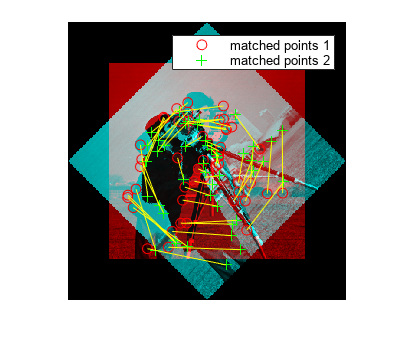

I1 = imread('cameraman.tif');

I2 = imrotate(I1,45);

% Detect SURF features. Other feature detectors can be used too.

points1 = detectSURFFeatures(I1);

points2 = detectSURFFeatures(I2);

% Extract features from images

[f1, vpts1] = extractFeatures(I1, points1); %f1-features % Validpoints

[f2, vpts2] = extractFeatures(I2, points2);

% Match features between images

indexPairs = matchFeatures(f1, f2);

matchedPoints1 = vpts1(indexPairs(:, 1));

matchedPoints2 = vpts2(indexPairs(:, 2));

figure; showMatchedFeatures(I1,I2,matchedPoints1,matchedPoints2);

legend('matched points 1','matched points 2');